# Home Field Advantage in the English Premier League

Which teams in the 2015-2016 season of the English Premier League had a home winning record? How many of those teams also had an away winning record? Are there any teams that performed better away than at home? Do teams with home winning records win more at home because they score more goals or give up fewer goals?

## Load the data

Load the EPL standings.

load EPLresults

## Home vs. away scoring

Compare the home and away scoring for each team.

homegf = EPL.HomeGF;
awaygf = EPL.AwayGF;
morehomegoals = homegf > awaygf;

How many teams scored more goals at home than away?

nnz(morehomegoals)

ans = 15

## Home record vs. away record

Compare the number of wins and losses for each team. 

homewinning = EPL.HomeWins >= EPL.HomeLosses;
awaywinning = EPL.AwayWins >= EPL.AwayLosses;

How many teams had home winning records? Away winning records?

[nnz(homewinning) nnz(awaywinning)]

ans =     12     9


What are the names and ranks of the teams with both home and away winning records?

winning = homewinning & awaywinning;
winningTeams = EPL.Team(winning)

winningTeams = 8×1 string array
    "Arsenal"
    "Chelsea"
    "Leicester City"
    "Liverpool"
    "Manchester City"
    "Southampton"
    "Tottenham Hotspur"
    "West Ham United"


winningTeamRanks = find(winning)

winningTeamRanks =      1
     4
     7
     8
     9
    13
    17
    20


Did any teams perform better away than at home?

betteraway = EPL.Team(awaywinning & ~homewinning)

betteraway = "Everton"

## Home field advantage

Did every team have a home field advantage, by either having a winning home record or scoring more goals at home than away?

HFA = homewinning | morehomegoals;
HFAforAll = all(HFA)

HFAforAll = logical
   0


What gives the teams with winning home records their home advantage? Do they score more goals or concede fewer goals?

s = ["HomeGF","HomeGA","AwayGF","AwayGA"]

s = 1×4 string array
    "HomeGF"    "HomeGA"    "AwayGF"    "AwayGA"


overallgoals = mean(EPL{:,s})

overallgoals =    28.3500   22.9500   22.9500   28.3500


homewingoals = mean(EPL{homewinning,s})

homewingoals =    32.2500   20.1667   25.6667   25.6667


homewingoals - overallgoals

ans =     3.9000   -2.7833    2.7167   -2.6833


## Home vs. away goal differential

Plot the home goal difference against the away goal difference.

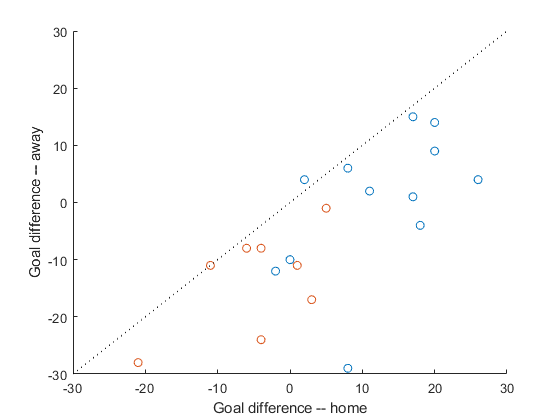

HGD = EPL.HomeGF - EPL.HomeGA;
AGD = EPL.AwayGF - EPL.AwayGA;
scatter(HGD(homewinning),AGD(homewinning))
hold on
scatter(HGD(~homewinning),AGD(~homewinning))
plot([-30 30],[-30 30],"k:")
xlabel("Goal difference -- home")
ylabel("Goal difference -- away")
hold off